上机1

在本作业中,我们会回顾基础的线性代数以及图像操作方法,让大家更好地熟悉本课程.

本作业的一个目的是让大家熟悉常用的一些函数库. 因此在你所需要实现的函数里，你可以参考一下帮助文件.

好了，祝大家好运~~

# 问题1：线性代数回顾

在本节中，我们将会回顾一下线性代数的基本概念，并且学习来操作向量和矩阵。通过本节学习，你将会学会基本的矩阵操作。

## 问题 1.1 

首先, 让我们定义以下矩阵和向量. 

提示：可以参阅帮助文件. 在下一个code block中，将 M 定义成 [4,3] 的矩阵,a 定义成 [1,3] 的行向量， b 定义成 [3,1的]列向量

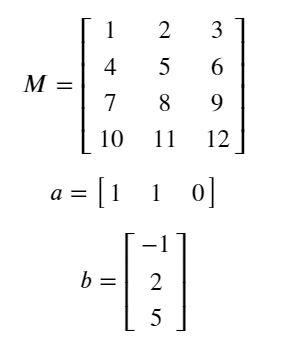

% 你的代码
M = [1, 2, 3; 4, 5, 6; 7, 8, 9; 10, 11, 12];
a = [1, 1, 0];
b = [-1; 2; 5];

% 你的代码
disp('M=');disp(M);disp('The size of M is: ');disp(size(M));

M=
     1     2     3
     4     5     6
     7     8     9
    10    11    12

The size of M is: 
     4     3



disp('a=');disp(a);disp('The size of a is: ');disp(size(a));

a=
     1     1     0

The size of a is: 
     1     3



disp('b=');disp(b);disp('The size of b is: ');disp(size(b));

b=
    -1
     2
     5

The size of b is: 
     3     1



## 问题1.2：请计算向量的点积，即$a^T b$

% 你的代码
aDotB = dot(a',b);

% 你的代码

disp('a点积b的计算结果是： ');

a点积b的计算结果是： 


disp(aDotB);

     1



## 问题1.3：请完成矩阵的乘法，即${\;a} b\;M\;a^T$

% 你的代码
result = a * b * M * a';

% 你的代码

disp('计算结果是： ');

计算结果是： 


disp(result);

     3
     9
    15
    21



## 问题1.4：利用svd()函数计算矩阵M的奇异值

% 你的代码
result = svd(M);
% 你的代码
disp('矩阵的前两个奇异值是：');

矩阵的前两个奇异值是：


disp(result(1:2));

   25.4624
    1.2907



## 问题1.5：利用eig()函数计算矩阵MM的特征值及特征向量：


$$\textrm{MM}=\left\lbrack \begin{array}{ccc}
1 & 2 & 3\\
4 & 5 & 6\\
7 & 8 & 9
\end{array}\right\rbrack$$


% 你的代码
MM = [1, 2, 3; 4, 5, 6; 7, 8, 9];

[val, vec] = eig(MM);
% 你的代码
disp('Eigenvalues =');

Eigenvalues =


disp(val);

   -0.2320   -0.7858    0.4082
   -0.5253   -0.0868   -0.8165
   -0.8187    0.6123    0.4082



disp('Eigenvectors =');

Eigenvectors =


disp(vec);

   16.1168         0         0
         0   -1.1168         0
         0         0   -0.0000



# 第二部分: 图像操作

现在你已经熟悉怎么利用matlab来操作矩阵和向量了. 现在让我们载入一些图片，将它们视作矩阵，并且对它们进行一些操作。

## 问题2.1：请载入图片image1以及图片image2并进行显示

image1_path = './image1.jpg'

image1_path = './image1.jpg'

image2_path = './image2.jpg'

image2_path = './image2.jpg'

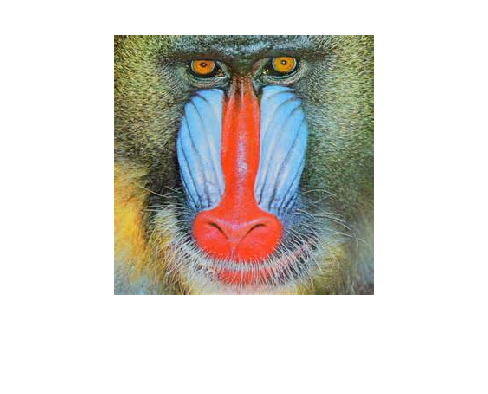


% 你的代码
img1 = imread(image1_path);
imshow(img1);

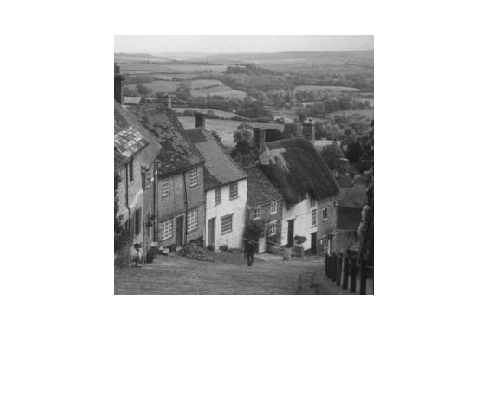

% 你的代码
img2 = imread(image2_path);
imshow(img2);

## 问题 2.2

完成并运行函数 `dim_image()`，将每个像素点变为$x_n =0\ldotp 5*\;x_p^2$ , 其中$x_n$ 表示新的像素值 $x_p$ 表示原始像素值.

注意: 请先将原图像的像素值进行归一化到[0,1], 再按照上述公式使得像素值变小。进而整幅图片的亮度都会降低。

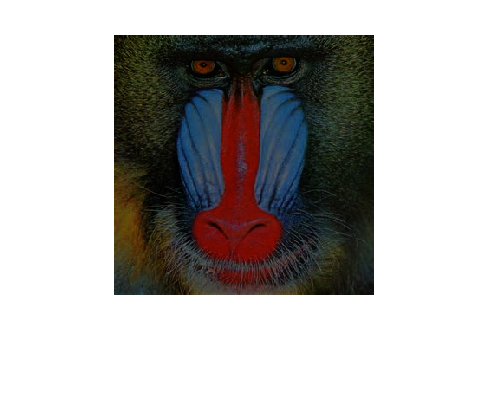

% 你的代码
img1 = imread("./image1.jpg");

new_image = dim_image(img1);
imshow(new_image);

## 问题 2.3 

完成并运行`convert_to_grey_scale`函数，将图片转为灰度图。可以发现彩色图有三个通道，而灰度图只有一个通道。

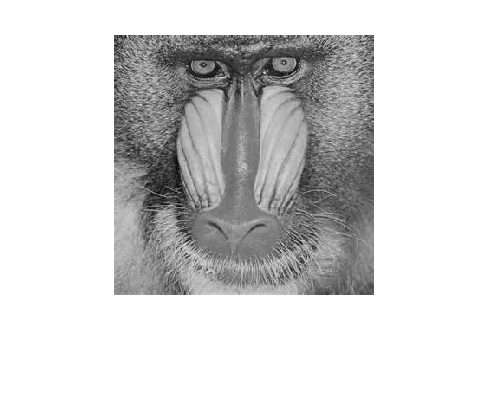

img1 = imread("./image1.jpg");

gray_image = convert_to_grey_scale(img1);
imshow(gray_image);

## 问题 2.4 

完成并运行函数 `rgb_exclusion(img,channel)`, 将输入图片分解为三个通道: R, G 以及 B。 同时将指定的通道从返回图片中去除。 

img1 = imread("./image1.jpg");
without_red = rgb_exclusion(img1, 'R')

without_red = 300×300×3 uint8 数组
without_red(:,:,1) =

   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0 

without_green = rgb_exclusion(img1, 'G')

without_green = 300×300×3 uint8 数组
without_green(:,:,1) =

    91    81    94    96    55   116    70    68    33   107   122    71    73    55   127   209   131    50   153   132   131   125   105    99   115   156   163   159   114   112    88    83    96   131   168   160   135   142   132    87   174   180    88    63   160   107   125   113   150   109    87    86    90   168   132    64    87   110   131   118   144    63    70    91   151   129   159   178   179   156    76   165   172   174   138   170    97   164    90    58    77   101    98   138   124   116   111   110   106   135   114    93    63    96    60   119   153    94    99   102    59   136    96    91    68    85   128   124   112   106   143   102   109   174    98   124   191   128    95    96    94   112   100    91    98   119   116    58   126    99   145   101   138    68    98    29    45   109   133    95   102    77    77    96    86   131   159   139   101    78    75    77    74    63    93   102    9

without_blue = rgb_exclusion(img1, 'B')

without_blue = 300×300×3 uint8 数组
without_blue(:,:,1) =

    91    81    94    96    55   116    70    68    33   107   122    71    73    55   127   209   131    50   153   132   131   125   105    99   115   156   163   159   114   112    88    83    96   131   168   160   135   142   132    87   174   180    88    63   160   107   125   113   150   109    87    86    90   168   132    64    87   110   131   118   144    63    70    91   151   129   159   178   179   156    76   165   172   174   138   170    97   164    90    58    77   101    98   138   124   116   111   110   106   135   114    93    63    96    60   119   153    94    99   102    59   136    96    91    68    85   128   124   112   106   143   102   109   174    98   124   191   128    95    96    94   112   100    91    98   119   116    58   126    99   145   101   138    68    98    29    45   109   133    95   102    77    77    96    86   131   159   139   101    78    75    77    74    63    93   102    95 

disp(size(without_red));

   300   300     3




disp('下图去除了Red通道.');

下图去除了Red通道.


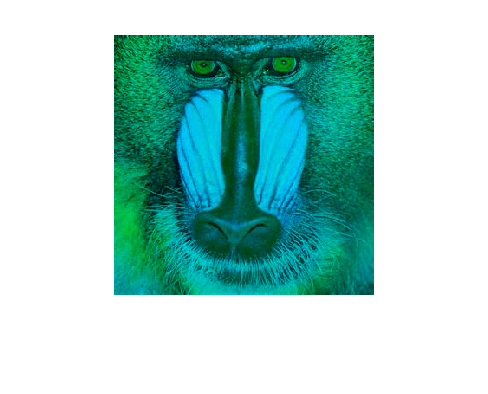

imshow(without_red);


disp('下图去除了Green通道.');

下图去除了Green通道.


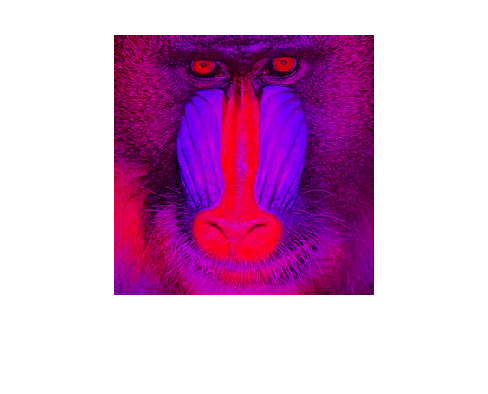

imshow(without_green);


disp('下图去除了Blue通道.');

下图去除了Blue通道.


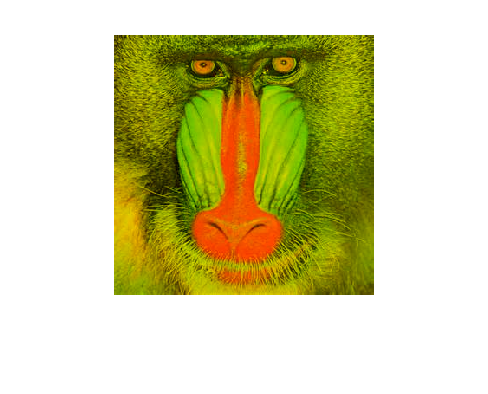

imshow(without_blue);

## 问题 2.5

完成并运行函数 `lab_decomposition`, 将输入图片分解为L,A,B三个通道，返回指定的通道图片。

image1 = imread("./image1.jpg");
image_l = lab_decomposition(image1, 'L');
image_a = lab_decomposition(image1, 'A');
image_b = lab_decomposition(image1, 'B');


disp('只有 L 通道.');

只有 L 通道.


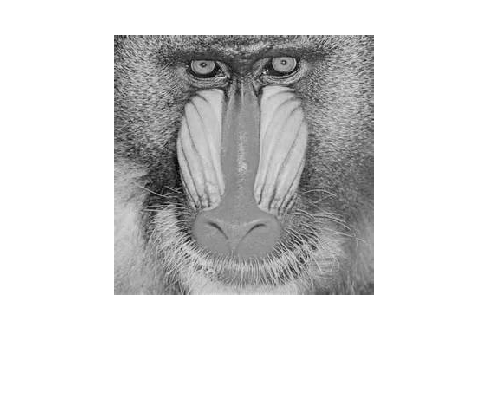

imshow(image_l);


disp('只有 a 通道.');

只有 a 通道.


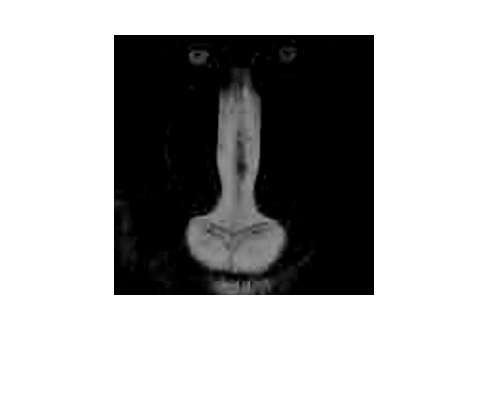

imshow(image_a);


disp('只有 b 通道.');

只有 b 通道.


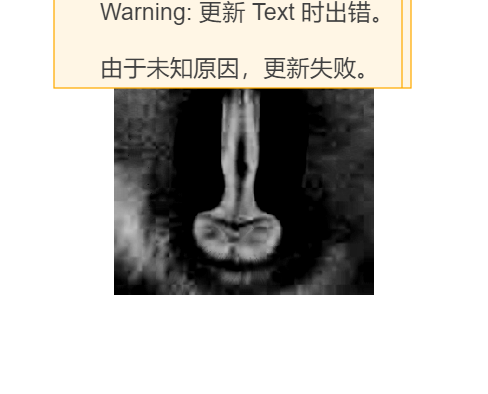

imshow(image_b);

## 问题:

用一两句话解释一下Lab分别代表什么，同时如果拿掉L通道和a通道，会发生什么？

## 你的答案:

L 代表明度，a 代表从绿色到红色的分量，b代表从蓝色到黄色的分量。如果只剩b通道，图片会按照饱和度从低到高显示蓝色 => 灰色 => 黄色。

## 问题 2.6 

完成并运行函数 `hsv_decomposition()`, 将输入图片分解成 H, S 以及 V 三个通道，并且返回指定的图像通道。 

imgage1 = imread("./image1.jpg");
image_h = hsv_decomposition(image1, 'H');
image_s = hsv_decomposition(image1, 'S');
image_v = hsv_decomposition(image1, 'V');

disp('只有 H 通道.');

只有 H 通道.


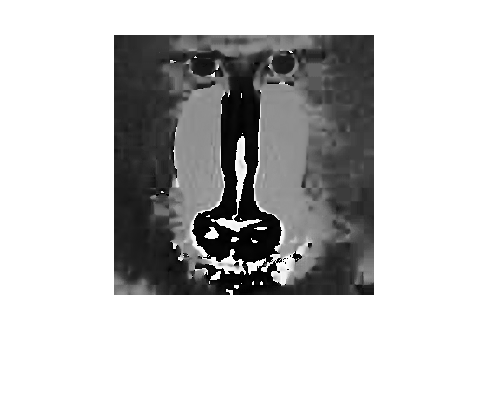

imshow(image_h);


disp('只有 S 通道.');

只有 S 通道.


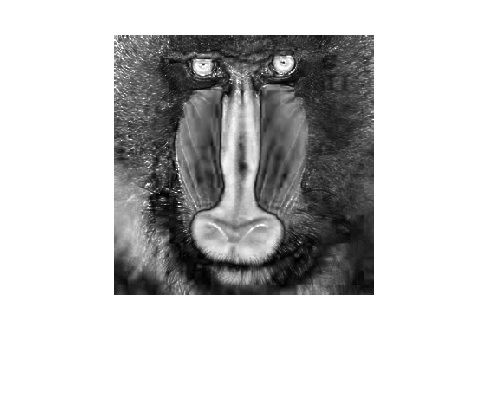

imshow(image_s);


disp('只有 V 通道.');

只有 V 通道.


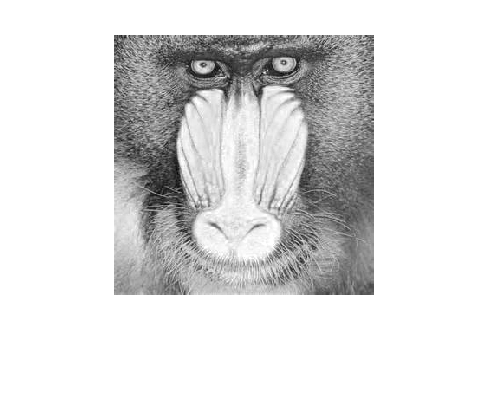

imshow(image_v);

## 问题:

用一两句话解释一下H S V分别代表什么，同时如果拿掉H通道和S通道，会发生什么？

## 你的答案:

H代表色调，S代表饱和度，V代表明度。如果只剩V通道，那么图片是一张灰度图片，按亮度从低到高显示黑色 => 白色。

## 问题 2.7 

完成并运行函数 `mix_images`：创建一幅新的图片，使得它的左半部分是图片1，右半部分是图片2，并且去掉指定的图像通道（R,G,或者B）。 

你会看到新图像的左半部分是猴子，并且没有红色通道，而图像的右半部分是一间房子，并且没有绿色通道。

提示：两张图像的尺寸是一样的，因此不需要进行额外的像素填充。

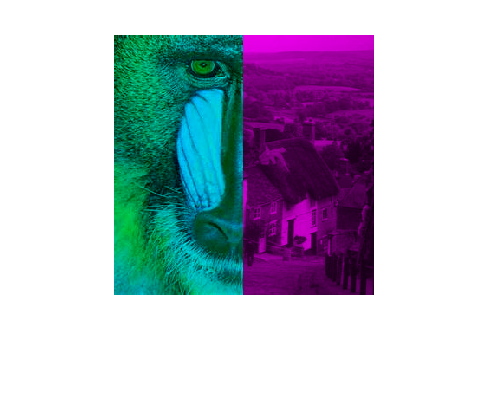

image1 = imread("./image1.jpg");
image2 = imread("./image2.jpg");
image_mixed = mix_images(image1, image2, 'R', 'G');
imshow(image_mixed);

## 问题 2.8

完成并运行`mix_quadrants`函数。

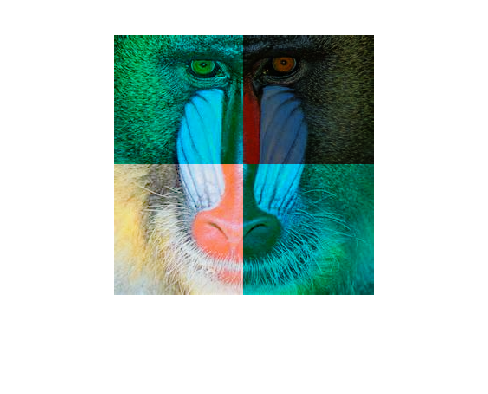

image1 = imread("./image1.jpg");
mixed_quadrants = mix_quadrants(image1);
imshow(mixed_quadrants);